# HURRICANE HARVEY REPORT 

## **Introduction**

In 2017, Hurricane Harvey became one of the costliest hurricanes on record, causing approximately $125 billion in damage. Most of the damage was caused from flooding with some areas receiving over 40 inches (102 cm) of rain.

Hurricanes are large weather events with a specific definition – a rotating low-pressure weather system with sustained winds of 74+ mph (119 km/h). Harvey became a hurricane August 24th, made landfall on the 25th, and was downgraded to a tropical storm on August 26th.

The impact of Harvey was felt over much more than just 3 days. In the 2017 storm events data set, Harvey related events are reported beginning August 17th and end September 3rd as the system moved north and east across the United States. Flooding, thunderstorms, hail, and tornadoes are just a few of the weather events related to Harvey.

## Background and Scope

### Import the Data

importing Data.

opts = delimitedTextImportOptions("NumVariables", 24);

% Specify range and delimiter
opts.DataLines = [2, Inf];
opts.Delimiter = ",";

% Specify column names and types
opts.VariableNames = ["EpisodeID", "Event_ID", "State", "Year", "Month", "Event_Type", "CZ_Name", "Begin_Date_Time", "Timezone", "End_Date_Time", "Injuries_Direct", "Injuries_Indirect", "Deaths_Direct", "Deaths_Indirect", "Damage_Property", "Property_Cost", "Damage_Crops", "Crop_Cost", "Begin_Lat", "Begin_Lon", "End_Lat", "End_Lon", "Episode_Narrative", "Event_Narrative"];
opts.VariableTypes = ["double", "double", "categorical", "double", "categorical", "categorical", "categorical", "datetime", "double", "datetime", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "double", "categorical", "string"];

% Specify file level properties
opts.ExtraColumnsRule = "ignore";
opts.EmptyLineRule = "read";

% Specify variable properties
opts = setvaropts(opts, "Event_Narrative", "WhitespaceRule", "preserve");
opts = setvaropts(opts, ["State", "Month", "Event_Type", "CZ_Name", "Episode_Narrative", "Event_Narrative"], "EmptyFieldRule", "auto");
opts = setvaropts(opts, "Begin_Date_Time", "InputFormat", "yyyy-MM-dd HH:mm:ss");
opts = setvaropts(opts, "End_Date_Time", "InputFormat", "yyyy-MM-dd HH:mm:ss");
opts = setvaropts(opts, ["Timezone", "Damage_Property", "Damage_Crops"], "TrimNonNumeric", true);
opts = setvaropts(opts, ["Timezone", "Damage_Property", "Damage_Crops"], "ThousandsSeparator", ",");

% Import the data
StormEvents2017finalProject2 = readtable("F:\Programming\Practical data science with Matlab\Exploratory Data Analysis\StormEvents\StormEvents_2017_finalProject.csv", opts)

StormEvents2017finalProject2 = 57005×24 table
    EpisodeID      Event_ID         State         Year     Month            Event_Type                               CZ_Name                           Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                            

### Two States Most Impacted by Harvey

these are the states worst affected 

StormEvents2017finalProject1 = StormEvents2017finalProject2(ismember(StormEvents2017finalProject2.State,{'ARKANSAS','KENTUCKY','LOUISIANA','MISSISSIPPI','NORTH CAROLINA','TENNESSEE','TEXAS'}),:);

StormEvents2017finalProject1 = StormEvents2017finalProject1(ismember(StormEvents2017finalProject1.Event_Type,{'Coastal Flood','Flash Flood','Flood','Hail','Hurricane','Thunderstorm Wind','Tornado'}),:);
StormEvents2017finalProject1 = StormEvents2017finalProject1(StormEvents2017finalProject1.End_Date_Time < '2017-09-04 00:00:01' | ismissing(StormEvents2017finalProject1.End_Date_Time),:);
StormEvents2017finalProject1 = StormEvents2017finalProject1(StormEvents2017finalProject1.Begin_Date_Time >= '2017-08-16 00:00:00' & StormEvents2017finalProject1.Begin_Date_Time < '2017-9-03 00:00:01' | ismissing(StormEvents2017finalProject1.Begin_Date_Time),:);
groupsummary(StormEvents2017finalProject1,"State","sum","Property_Cost");
ans = sortrows(ans,'sum_Property_Cost','descend')

ans = 7×3 table
        State         GroupCount    sum_Property_Cost
    ______________    __________    _________________

    TEXAS                214           4.7778e+10    
    LOUISIANA             61           7.5277e+07    
    NORTH CAROLINA        56           1.2332e+07    
    MISSISSIPPI           26             6.61e+05    
    KENTUCKY              20             4.35e+05    
    TENNESSEE             26             3.97e+05    
    ARKANSAS              36                56000    


### Table of Events for Two Most Impacted States

the two most affected states

StormEvents2017finalProject1;

StormEvents2017finalProject1 = StormEvents2017finalProject1(ismember(StormEvents2017finalProject1.State,{'LOUISIANA','TEXAS'}),:)

StormEvents2017finalProject1 = 275×24 table
    EpisodeID      Event_ID     State    Year    Month        Event_Type         CZ_Name        Begin_Date_Time      Timezone       End_Date_Time       Injuries_Direct    Injuries_Indirect    Deaths_Direct    Deaths_Indirect    Damage_Property    Property_Cost    Damage_Crops    Crop_Cost    Begin_Lat    Begin_Lon    End_Lat    End_Lon                                                                                                                                                                                                                                                     

## Visualizations

### Figure of Event Types

 the type and number of occurances for events related to Harvey in the two states

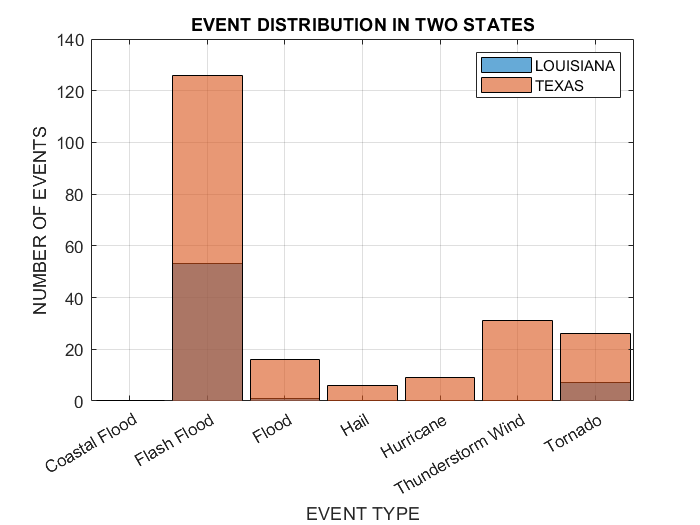

StormEvents2017finalProject1L = StormEvents2017finalProject1(StormEvents2017finalProject1.State ~= 'TEXAS',:);

StormEvents2017finalProject1L.Event_Type = removecats(StormEvents2017finalProject1L.Event_Type,{'Astronomical Low Tide','Avalanche','Blizzard','Cold/Wind Chill','Debris Flow','Dense Fog','Dense Smoke','Drought','Dust Devil','Dust Storm','Excessive Heat','Extreme Cold/Wind Chill','Freezing Fog','Frost/Freeze','Funnel Cloud','Heat','Heavy Rain','Heavy Snow','High Surf','High Wind','Ice Storm','Lake-Effect Snow','Lakeshore Flood','Lightning','Marine Hail','Marine High Wind','Marine Hurricane/Typhoon','Marine Strong Wind','Marine Thunderstorm Wind','Marine Tropical Depression','Marine Tropical Storm','Rip Current','Sleet','Sneakerwave','Storm Surge/Tide','Strong Wind','Tropical Depression','Tropical Storm','Waterspout','Wildfire','Winter Storm','Winter Weather'});
 histogram(StormEvents2017finalProject1L.Event_Type)
 hold on
StormEvents2017finalProject1T = StormEvents2017finalProject1(StormEvents2017finalProject1.State ~= 'LOUISIANA',:);

StormEvents2017finalProject1T.Event_Type = removecats(StormEvents2017finalProject1T.Event_Type,{'Avalanche','Astronomical Low Tide','Blizzard','Cold/Wind Chill','Debris Flow','Dense Fog','Dense Smoke','Drought','Dust Devil','Dust Storm','Excessive Heat','Extreme Cold/Wind Chill','Freezing Fog','Frost/Freeze','Funnel Cloud','Heat','Heavy Rain','Heavy Snow','High Surf','High Wind','Ice Storm','Lake-Effect Snow','Lakeshore Flood','Lightning','Marine Hail','Marine High Wind','Marine Hurricane/Typhoon','Marine Strong Wind','Marine Thunderstorm Wind','Marine Tropical Depression','Marine Tropical Storm','Rip Current','Sleet','Sneakerwave','Storm Surge/Tide','Strong Wind','Tropical Depression','Tropical Storm','Waterspout','Wildfire','Winter Storm','Winter Weather'});
 histogram(StormEvents2017finalProject1T.Event_Type)
 hold off
grid on
legend({'LOUISIANA','TEXAS'})

title('EVENT DISTRIBUTION IN TWO STATES')
xlabel('EVENT TYPE')
ylabel('NUMBER OF EVENTS')

### Figure of Event Locations

 the location of events in the two states.

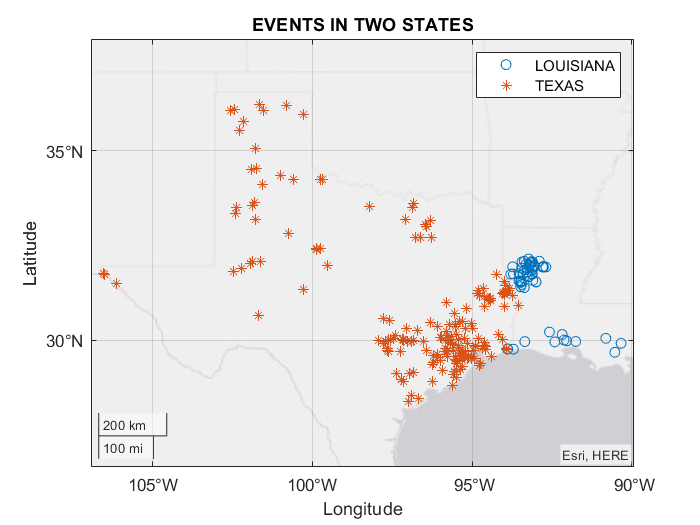

geoscatter(StormEvents2017finalProject1L.Begin_Lat,StormEvents2017finalProject1L.Begin_Lon)
hold on
geoscatter(StormEvents2017finalProject1T.Begin_Lat,StormEvents2017finalProject1T.Begin_Lon,"Marker","*")
hold off

legend({'LOUISIANA','TEXAS'})

title('EVENTS IN TWO STATES')

## Analysis

### Three Counties with Most Events in State 1

 three counties with the most events in state 1.

groupsummary(StormEvents2017finalProject1T,"CZ_Name");

ans = sortrows(ans,'GroupCount','descend')

ans = 80×2 table
     CZ_Name      GroupCount
    __________    __________

    HARRIS            19    
    GALVESTON         14    
    FORT BEND         12    
    ANGELINA          10    
    BRAZORIA          10    
    SABINE            10    
    BASTROP            8    
    CHAMBERS           7    
    CALDWELL           6    
    MONTGOMERY         5    
    MATAGORDA          4    
    WHARTON            4    
    CALHOUN            3    
    EL PASO            3    
    FAYETTE            3    
    LIBERTY            3    


### Three Counties with Most Events in State 2

Either type out, show in a table, or show in a clear visualization the three counties with the most events in state 2.

groupsummary(StormEvents2017finalProject1L,"CZ_Name");

ans = sortrows(ans,'GroupCount','descend')

ans = 15×2 table
      CZ_Name       GroupCount
    ____________    __________

    NATCHITOCHES        19    
    SABINE              13    
    RED RIVER            8    
    WINN                 5    
    CAMERON              3    
    VERMILION            3    
    DE SOTO              2    
    ACADIA               1    
    BEAUREGARD           1    
    CALCASIEU            1    
    IBERIA               1    
    LAFAYETTE            1    
    LAFOURCHE            1    
    ST. CHARLES          1    
    ST. JAMES            1    


### Three Counties with Highest Property Cost in State 1

Either type out, show in a table, or show in a clear visualization the three counties with the highest property damage in state 1. *Be sure to include the dollar amount*. 

groupsummary(StormEvents2017finalProject1T,"CZ_Name","sum","Property_Cost");

ans = sortrows(ans,'sum_Property_Cost','descend')

ans = 80×3 table
      CZ_Name       GroupCount    sum_Property_Cost
    ____________    __________    _________________

    HARRIS              19           1.0001e+10    
    GALVESTON           14                1e+10    
    FORT BEND           12           8.0043e+09    
    MONTGOMERY           5                7e+09    
    JEFFERSON            2                3e+09    
    BRAZORIA            10           2.0008e+09    
    ARANSAS              1             1.75e+09    
    ORANGE               2              1.5e+09    
    NUECES               1                1e+09    
    HARDIN               1                6e+08    
    WALKER               3                6e+08    
    REFUGIO              2                5e+08    
    SAN PATRICIO         1                5e+08    
    SAN JACINTO          2              3.5e+08    
    POLK                 1                3e+08 

### Three Counties with Highest Property Cost in State 2

Either type out, show in a table, or show in a clear visualization the three counties with the highest property damage in state 2. *Be sure to include the dollar amount*. 

groupsummary(StormEvents2017finalProject1L,"CZ_Name","sum","Property_Cost");

ans = sortrows(ans,'sum_Property_Cost','descend')

ans = 15×3 table
      CZ_Name       GroupCount    sum_Property_Cost
    ____________    __________    _________________

    CALCASIEU            1               6e+07     
    BEAUREGARD           1             1.5e+07     
    ACADIA               1               2e+05     
    CAMERON              3               72000     
    VERMILION            3                5000     
    DE SOTO              2                   0     
    IBERIA               1                   0     
    LAFAYETTE            1                   0     
    LAFOURCHE            1                   0     
    NATCHITOCHES        19                   0     
    RED RIVER            8                   0     
    SABINE              13                   0     
    ST. CHARLES          1                   0     
    ST. JAMES            1                   0     
    WINN                 5                   0  

## Conclusions and Recommendations

The insurance company should send people to the state of TEXAS and LOUISIANA. coming to counties, as seen by the above summary table ACADIA, BEAUREGARD and CALCASIEU are most affected in LOUISIANA. HARRIS, GALVISTON and FORT BEND are worst hit by TEXAS.these results are validating also about the geoplot shown.